**2계 제차 선형 상미분방정식의 복소근의 경우: 특성 방정식 및 해**

**주어진 예제 방정식**

**방정식**


$$y'' + 2y' + 5 = 0$$


**초기 조건**


$$y(0) = 1, \quad y'(0) = 3$$


**1. 특성 방정식**

- 주어진 방정식의 특성 방정식은 다음과 같습니다:


$$\lambda^2 + a\lambda + b = 0$$


- 여기서 $a^2 - 4b < 0$일 때, 두 개의 복소근이 존재합니다.

**2. 복소근**

- 복소근의 형태는 다음과 같습니다:

$\lambda = \frac{-a \pm \sqrt{a^2 - 4b}}{2}$��

- 이 경우 두 개의 복소근은 다음과 같이 주어집니다:


$$\lambda_1 = -\frac{a}{2} + i\omega, \quad \lambda_2 = -\frac{a}{2} - i\omega$$


여기서 $\omega = \frac{\sqrt{4b - a^2}}{2}$입니다.

**3. 일반 해의 형태**

- 복소근에 해당하는 두 해는 다음과 같이 주어집니다:


$$y_1 = e^{-\frac{a}{2}x} \cos(\omega x), \quad y_2 = e^{-\frac{a}{2}x} \sin(\omega x)$$


- 일반 해는 다음과 같이 표현됩니다:


$$y = e^{-\frac{a}{2}x}(A \cos(\omega x) + B \sin(\omega x))$$


**4. 예제 방정식**

- **주어진 예제**:


$$y'' + 2y' + 5 = 0, \quad y(0) = 1, \quad y'(0) = 3$$


**5. 해 구하기**

- 특성 방정식을 풀면 복소근을 얻습니다:


$$\lambda = -1 \pm 2i$$


- 따라서, 일반 해는 다음과 같습니다:


$$y(x) = e^{-x}(A \cos(2x) + B \sin(2x))$$


**6. 초기 조건을 이용한 상수 결정****초기 조건 **$y(0) = 1$


$$y(0) = e^{0}(A \cos(0) + B \sin(0)) = A = 1$$


**초기 조건 **$y'(0) = 3$

- $y'(x)$을 미분합니다:


$$y'(x) = e^{-x} \left( -A \cos(2x) - 2A \sin(2x) + B \cdot 2 \cos(2x) + B \cdot (-\sin(2x)) \right)$$


- $y'(0)$을 대입합니다:


$$y'(0) = -e^{0}(A \cdot 0 + 2B) = -1 + 2B$$


이 식에 $y'(0) = 3$을 대입하면:


$$-1 + 2B = 3$$


따라서,


$$2B=4\Longrightarrow B=2$$


**7. 최종 해**

모든 상수를 대입하면 최종 해는 다음과 같습니다:


$$y(x) = e^{-x} \left( \cos(2x) + 2 \sin(2x) \right)$$


% 매개변수 설정
syms y(x) A B

% 방정식 정의
Dy = diff(y, x); % y'의 정의
D2y = diff(Dy, x); % y''의 정의

% 방정식 설정
ode = D2y + 2*Dy + 5 == 0;

% 일반 해 구하기
yGeneral = dsolve(ode);

% 초기 조건을 위한 A와 B 설정
A = sym('A');
B = sym('B');

% 일반 해의 형태
yGeneral = exp(-x) * (A * cos(2*x) + B * sin(2*x));

% 초기 조건 설정
% y(0) = 1
% y'(0) = 3
cond1 = subs(yGeneral, x, 0) == 1;   % 첫 번째 초기 조건
cond2 = subs(diff(yGeneral, x), x, 0) == 3; % 두 번째 초기 조건

% 초기 조건을 포함하여 해를 구하기
[A_value, B_value] = solve([cond1, cond2], [A, B]);

% A와 B를 yGeneral에 대입하여 최종 해 구하기
ySolution = subs(yGeneral, {A, B}, {A_value, B_value});

% 결과 출력
disp('방정식의 해는:');

방정식의 해는:


pretty(ySolution)

exp(-x) (cos(2 x) + sin(2 x) 2)



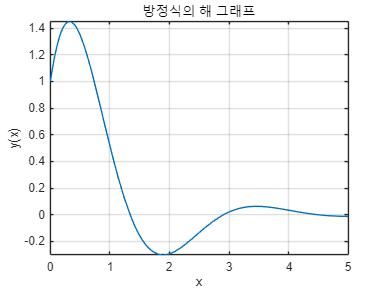


% 해의 그래프 그리기
fplot(ySolution, [0, 5]); % 0부터 5까지의 범위
title('방정식의 해 그래프');
xlabel('x');
ylabel('y(x)');
grid on;

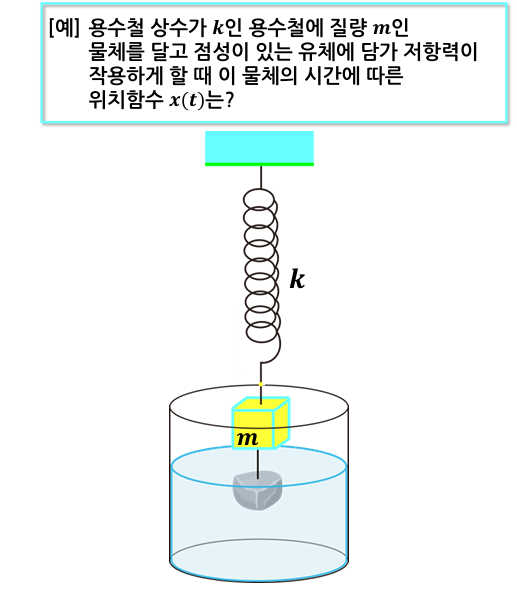

**질량-댐퍼-스프링 시스템 모델링**

**1. 뉴턴의 법칙**

- **운동 방정식**:


$$F = mx''$$


여기서 $F$는 물체에 작용하는 총 힘이며, $m$은 질량, $x\prime \prime $는 위치의 두 번째 미분(가속도)을 나타냅니다.

**2. 용수철 힘**

- **용수철의 힘**:


$$F_s = -kx$$


- 여기서 $k$는 용수철 상수($N/m$)로, 스프링의 강도를 나타내며, $x$는 용수철의 변위를 나타냅니다.

- 이 힘은 후크의 법칙을 따르며, 스프링의 변위에 비례하여 작용합니다.

**3. 점성이 있는 유체에 의한 감쇠력**

- **감쇠력**:


$$F_d = -cy'$$


- 여기서 $c$는 감쇠 상수로, 유체의 점성을 나타냅니다.

- $y\prime $는 위치의 첫 번째 미분(속도)로, 물체의 속도에 비례하여 작용하는 힘입니다.

**4. 전체 시스템의 운동 방정식**

위의 힘들을 모두 고려하면, 전체 운동 방정식은 다음과 같이 표현할 수 있습니다:


$$mx'' + cx' + kx = 0$$


이 방정식은 질량-댐퍼-스프링 시스템의 동역학을 설명합니다. 여기서 각 항은 질량에 의한 관성력, 감쇠력, 그리고 스프링의 힘을 나타냅니다.

**5. 미분방정식 구조**

**미분방정식**

- 질량 $m$, 감쇠 상수 $c$, 스프링 상수 $k$를 고려하여 미분방정식은 다음과 같이 표현됩니다:


$$m y'' + c y' + k y = 0$$


- 여기서:

- $y\prime \prime $는 위치 $y$에 대한 두 번째 미분 (가속도)

- $y\prime $는 위치 $y$에 대한 첫 번째 미분 (속도)

- $y$는 질량의 위치를 나타냅니다.

**6. 특성방정식**

- 주어진 미분방정식의 특성방정식은 다음과 같이 설정할 수 있습니다:


$$\lambda^2 + \frac{c}{m} \lambda + \frac{k}{m} = 0$$


- 여기서 $\lambda$는 고유값으로 시스템의 동적 특성을 나타냅니다.

**고유값**

- 고유값은 다음과 같이 계산됩니다:


$$\lambda_1 = -\alpha + \beta, \quad \lambda_2 = -\alpha - \beta$$


여기서,

$\alpha = \frac{c}{2m}, \quad \beta = \frac{1}{2m} \sqrt{c^2 - 4mk}$�

**7. 해의 종류**

- **과도 감쇠**: $c^2 > 4mk$일 때, 두 개의 서로 다른 실근이 존재합니다.

- **임계 감쇠**: $c^2 = 4mk$일 때, 중복된 실근이 존재합니다.

- **부족 감쇠**: $c^2 < 4mk$일 때, 두 개의 복소근이 존재합니다.

**(1) 과감쇠 (Overdamping)**

- **조건**:


$$c^2 > 4mk$$


- 이 조건이 만족될 때, 두 개의 서로 다른 실근이 존재합니다.

- **해의 형태**:


$$y(t) = c_1 e^{-(\alpha - \beta)t} + c_2 e^{-(\alpha + \beta)t}$$


- 여기서 $c_1$과 $c_2$는 초기 조건에 따라 결정되는 상수이며, α\alphaα와 β\betaβ는 각각 감쇠 계수 및 스프링의 주파수를 나타냅니다.

**(2) 임계감쇠 (Critical Damping)**

- **조건**:


$$c^2 = 4mk$$


- 이 조건이 만족될 때, 중복된 실근이 존재합니다.

- **해의 형태**:


$$y(t) = (c_1 + c_2 t)e^{-\alpha t}$$


- 이 경우, 감쇠가 최대화되어 시스템이 최단 시간에 정지하게 됩니다. 초기 조건에 따라 $c_1$과 $c_2$�를 결정합니다.

**(3) 저감쇠 (Underdamping)****조건**

- **조건**: 


$$c^2 < 4mk$$


- 이 조건이 만족될 때, 시스템은 복소근을 갖게 되어 진동을 합니다.

**해의 형태**

- **위치 함수**: 


$$y(t) = e^{-\alpha t}(A \cos(\omega t) + B \sin(\omega t))$$


- 여기서:

- $e^{-\alpha t}$는 감쇠 항으로, 시간에 따라 진폭이 감소함을 나타냅니다.

- $A$와 $B$는 초기 조건에 따라 결정되는 상수입니다.

**주파수 **$\omega$

- **주파수 정의**: 

$\omega = \frac{1}{2m} \sqrt{4mk - c^2}$�

- 주파수 $\omega$는 시스템의 진동 주기를 결정하며, 스프링 상수와 감쇠 계수에 따라 달라집니다.

사례:

- 질량 $m = 1500 \, \text{kg}$ (차량의 무게)

- 감쇠 계수 $c = 1000 \, \text{Ns/m}$ (댐퍼의 감쇠 성능)

- 스프링 상수 $k = 20000 \, \text{N/m}$ (스프링의 강도)

**1. 과감쇠 (Overdamping)**

- **조건**: $c^2 > 4mk$

% 과감쇠 시스템 매개변수 설정
m = 1500; % 질량 (kg)
k = 20000; % 스프링 상수 (N/m)
c = 5000; % 감쇠 계수 (Ns/m), c^2 > 4mk

% 미분방정식
fprintf('과감쇠 미분방정식: m*y'''' + c*y'' + k*y = 0\n');

과감쇠 미분방정식: m*y'' + c*y' + k*y = 0



% 특성방정식
fprintf('과감쇠 특성방정식: lambda^2 + (c/m)*lambda + (k/m) = 0\n');

과감쇠 특성방정식: lambda^2 + (c/m)*lambda + (k/m) = 0



% 특정해
fprintf('과감쇠 특정해: y(t) = c_1*e^{-(alpha - beta)*t} + c_2*e^{-(alpha + beta)*t}\n');

과감쇠 특정해: y(t) = c_1*e^{-(alpha - beta)*t} + c_2*e^{-(alpha + beta)*t}


fprintf('여기서 alpha = c/(2*m), beta = sqrt(c^2 - 4*m*k)/(2*m)\n\n');

여기서 alpha = c/(2*m), beta = sqrt(c^2 - 4*m*k)/(2*m)



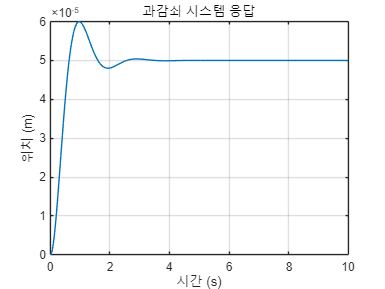


% 상태 공간 표현
A = [0 1; -k/m -c/m];
B = [0; 1/m];
C = [1 0]; % 출력은 위치
D = 0;

% 시스템 생성
sys = ss(A, B, C, D);

% 시간 설정
t = 0:0.01:10; % 0에서 10초까지, 0.01초 간격

% 초기 조건 설정 (y(0) = 0, y'(0) = 0)
initial_conditions = [0; 0];

% 입력으로 단위 계단 함수 추가
u = ones(size(t)) * 1; % 1N의 힘이 1초 동안 작용한다고 가정

% 시스템 응답 시뮬레이션
[y, t, x] = lsim(sys, u, t, initial_conditions);

% 그래프 출력
figure;
plot(t, y);
title('과감쇠 시스템 응답');
xlabel('시간 (s)');
ylabel('위치 (m)');
grid on;

**2. 임계감쇠 (Critical Damping)**

- **조건**: $c^2 = 4mk$

% 임계감쇠 시스템 매개변수 설정
m = 1500; % 질량 (kg)
k = 20000; % 스프링 상수 (N/m)
c = 2449.49; % 감쇠 계수 (Ns/m), c^2 = 4mk

% 미분방정식
fprintf('임계감쇠 미분방정식: m*y'''' + c*y'' + k*y = 0\n');

임계감쇠 미분방정식: m*y'' + c*y' + k*y = 0



% 특성방정식
fprintf('임계감쇠 특성방정식: lambda^2 + (c/m)*lambda + (k/m) = 0\n');

임계감쇠 특성방정식: lambda^2 + (c/m)*lambda + (k/m) = 0



% 특정해
fprintf('임계감쇠 특정해: y(t) = (c_1 + c_2*t)e^{-alpha*t}\n');

임계감쇠 특정해: y(t) = (c_1 + c_2*t)e^{-alpha*t}


fprintf('여기서 alpha = c/(2*m)\n\n');

여기서 alpha = c/(2*m)



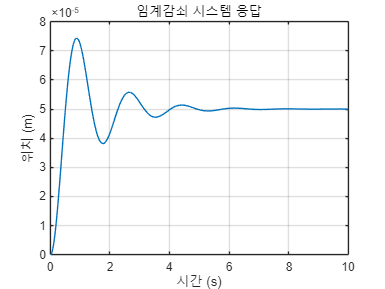


% 상태 공간 표현
A = [0 1; -k/m -c/m];
B = [0; 1/m];
C = [1 0]; % 출력은 위치
D = 0;

% 시스템 생성
sys = ss(A, B, C, D);

% 시간 설정
t = 0:0.01:10; % 0에서 10초까지, 0.01초 간격

% 초기 조건 설정 (y(0) = 0, y'(0) = 0)
initial_conditions = [0; 0];

% 입력으로 단위 계단 함수 추가
u = ones(size(t)) * 1; % 1N의 힘이 1초 동안 작용한다고 가정

% 시스템 응답 시뮬레이션
[y, t, x] = lsim(sys, u, t, initial_conditions);

% 그래프 출력
figure;
plot(t, y);
title('임계감쇠 시스템 응답');
xlabel('시간 (s)');
ylabel('위치 (m)');
grid on;

**3. 저감쇠 (Underdamping)**

- **조건**: $c^2 < 4mk$

% 저감쇠 시스템 매개변수 설정
m = 1500; % 질량 (kg)
k = 20000; % 스프링 상수 (N/m)
c = 500; % 감쇠 계수 (Ns/m), c^2 < 4mk

% 미분방정식
fprintf('저감쇠 미분방정식: m*y'''' + c*y'' + k*y = 0\n');

저감쇠 미분방정식: m*y'' + c*y' + k*y = 0



% 특성방정식
fprintf('저감쇠 특성방정식: lambda^2 + (c/m)*lambda + (k/m) = 0\n');

저감쇠 특성방정식: lambda^2 + (c/m)*lambda + (k/m) = 0



% 특정해
fprintf('저감쇠 특정해: y(t) = e^{-alpha*t}(A cos(omega*t) + B sin(omega*t))\n');

저감쇠 특정해: y(t) = e^{-alpha*t}(A cos(omega*t) + B sin(omega*t))


fprintf('여기서 alpha = c/(2*m), omega = 1/(2*m)*sqrt(4*m*k - c^2)\n\n');

여기서 alpha = c/(2*m), omega = 1/(2*m)*sqrt(4*m*k - c^2)



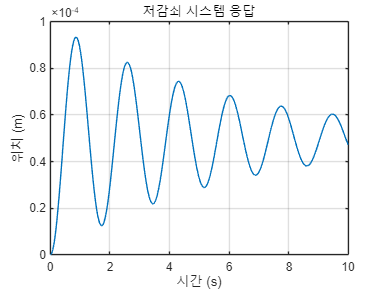


% 상태 공간 표현
A = [0 1; -k/m -c/m];
B = [0; 1/m];
C = [1 0]; % 출력은 위치
D = 0;

% 시스템 생성
sys = ss(A, B, C, D);

% 시간 설정
t = 0:0.01:10; % 0에서 10초까지, 0.01초 간격

% 초기 조건 설정 (y(0) = 0, y'(0) = 0)
initial_conditions = [0; 0];

% 입력으로 단위 계단 함수 추가
u = ones(size(t)) * 1; % 1N의 힘이 1초 동안 작용한다고 가정

% 시스템 응답 시뮬레이션
[y, t, x] = lsim(sys, u, t, initial_conditions);

% 그래프 출력
figure;
plot(t, y);
title('저감쇠 시스템 응답');
xlabel('시간 (s)');
ylabel('위치 (m)');
grid on;

**시스템 매개변수**

- 질량 $m = 2 \, \text{kg}$

- 스프링 상수 $k = 200 \, \text{N/m}$

- 감쇠 계수 $c = 0 \, \text{Ns/m}$ (마찰이나 점성이 없다고 가정)

- 초기 조건:

- 
$$x(0) = 0.1 \, \text{m}$$


- 
$$x'(0) = 0$$


**1. 미분 방정식**

마찰이 없는 경우, 미분 방정식은 다음과 같이 표현됩니다:


$$m x'' + k x = 0$$


이를 변형하면:


$$x'' + \frac{k}{m} x = 0$$


**2. 특성 방정식**

특성 방정식은 다음과 같습니다:


$$\lambda^2 + \frac{k}{m} = 0$$


여기서 λ\lambdaλ는 고유값입니다.

**3. 해 구하기**

주어진 파라미터에 따라 $\omega$를 계산합니다:


$$\omega = \sqrt{\frac{k}{m}} = \sqrt{\frac{200}{2}} = 10 \, \text{rad/s}$$


이 경우의 해는 다음과 같은 형태를 가집니다:


$$x(t) = A \cos(\omega t) + B \sin(\omega t)$$


**4. 초기 조건 적용**

주어진 초기 조건을 사용하여 $A$와 $B$를 구합니다.

- $x(0) = 0.1$:


$$x(0) = A \cdot \cos(0) + B \cdot \sin(0) = A = 0.1$$


- $x'(0) = 0$:


$$x'(t) = -A \omega \sin(\omega t) + B \omega \cos(\omega t)              $$



$$  x'(0) = -A \cdot 10 \cdot 0 + B \cdot 10 \cdot 1 = 10B                 
   $$



$$                   10B=0\Longrightarrow B=0$$


**5. 최종 해**

따라서 최종 해는 다음과 같습니다:


$$x(t) = 0.1 \cos(10t)$$


**진동수 계산**

주어진 파라미터에 따라 진동수 f는 다음과 같이 계산됩니다:


$$\omega =2\pi f=\sqrt{\frac{k}{m}}=10$$


$f=\frac{10}{2\pi }=\frac{5}{\pi }\;\left(H_z \right)$��

% 시스템 매개변수 설정
m = 2; % 질량 (kg)
k = 200; % 스프링 상수 (N/m)
c = 0; % 감쇠 계수 (Ns/m)

% 미분방정식 출력
fprintf('미분방정식: m*x'''' + k*x = 0\n');

미분방정식: m*x'' + k*x = 0



% 특성방정식 출력
fprintf('특성방정식: lambda^2 + (k/m) = 0\n');

특성방정식: lambda^2 + (k/m) = 0



% 주파수 계산
omega = sqrt(k/m);
fprintf('진동수 omega: %.2f rad/s\n', omega);

진동수 omega: 10.00 rad/s


fprintf('진동수 f: %.2f Hz\n', omega/(2*pi)); % 주파수 (Hz) 계산

진동수 f: 1.59 Hz



% 초기 조건 설정
x0 = 0.1; % x(0) = 0.1m
v0 = 0;   % x'(0) = 0

% 해의 형태 정의
syms t A B
A = x0; % A는 초기 위치
B = (v0 / omega); % B는 초기 속도에 따라 계산

% 최종 해
y = A * cos(omega * t); % 최종 해

% 결과 출력
fprintf('해: x(t) = %.2f * cos(%.2f * t)\n', x0, omega);

해: x(t) = 0.10 * cos(10.00 * t)


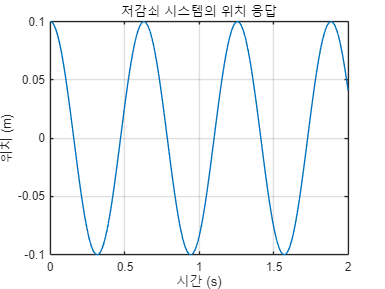


% 해의 그래프 그리기
t_vals = 0:0.01:2; % 0부터 2초까지
x_vals = double(subs(y, t, t_vals)); % y(t)를 계산

figure;
plot(t_vals, x_vals);
title('저감쇠 시스템의 위치 응답');
xlabel('시간 (s)');
ylabel('위치 (m)');
grid on;